## Lab 2.4

(a)定义并画出x1，h1，h2。

x1 = [1 1 1 1 0 0 0 0 0 0]
h1 = [0 -1 3 0 4]
h2 = [0 2 5 4 -1]
nx1 = 0:9
nh1 = 0:4
%画图
figure
subplot(3,1,1)
stem(nx1,x1)
legend('x1[n]')
xlabel('n')

subplot(3,1,2)
stem(nh1,h1)
legend('h1[n]')
xlabel('n')

subplot(3,1,3)
stem(nh1,h2)
legend('h2[n]')
xlabel('n')

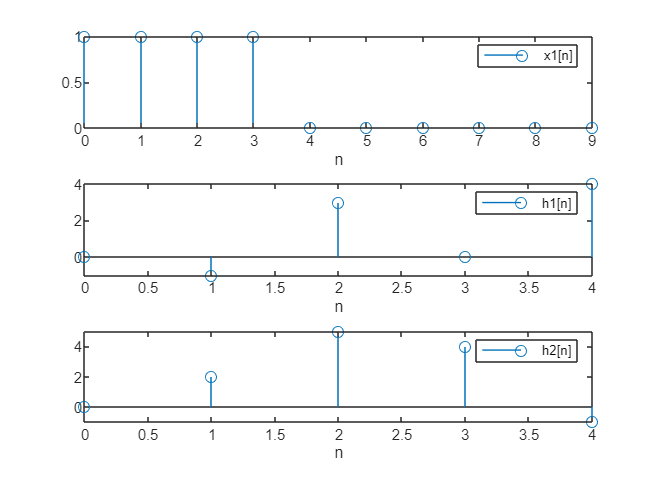

结论：如图所示。

(b)验证h1[n]*x1[n]等于x1[n]*h1[n]（其中*的意思是卷积）

%分别计算出y1[n]=h1[n]*x1[n],y2[n]=x1[n]*h1[n]
y1 = conv(h1,x1)
y2 = conv(x1,h1)
%画出y1，y2的图像，对比是否一致
figure
stem(nx1(1)+nh1(1):nx1(end)+nh1(end),y1)
hold on
stem(nx1(1)+nh1(1):nx1(end)+nh1(end),y2,'r','*')
legend('y1=h1[n]*x1[n]','y2=x1[n]*h1[n]')



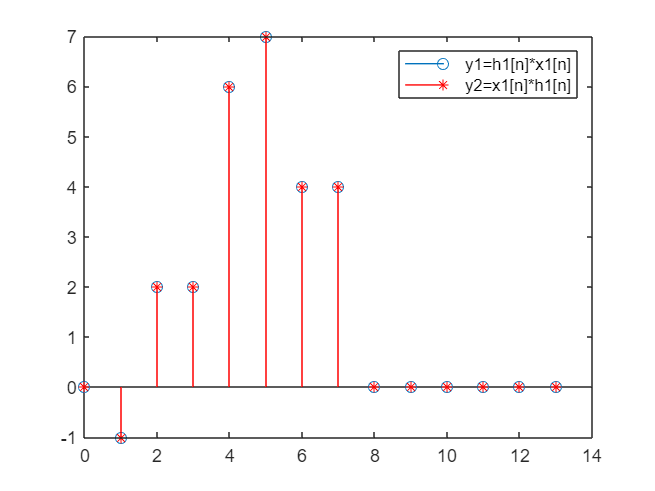

结论：如图，y1和y2相同，卷积的交换律成立。

(c)验证卷积的分配律，令y3[n]=x1[n]*h1[n]+x1[n]*h2[n],y4[n]=x1[n]*(h1[n]+h2[n]),判断y3是否等于y4

%计算y3，y4
y3=conv(x1,h1)+conv(x1,h2)
y4=conv(x1,h1+h2)
figure
stem(0:13,y3)
hold on
stem(0:13,y4,'r','+')
legend('y3[n]=x1[n]*h1[n]+x1[n]*h2[n]','y4[n]=x1[n]*(h1[n]+h2[n])')


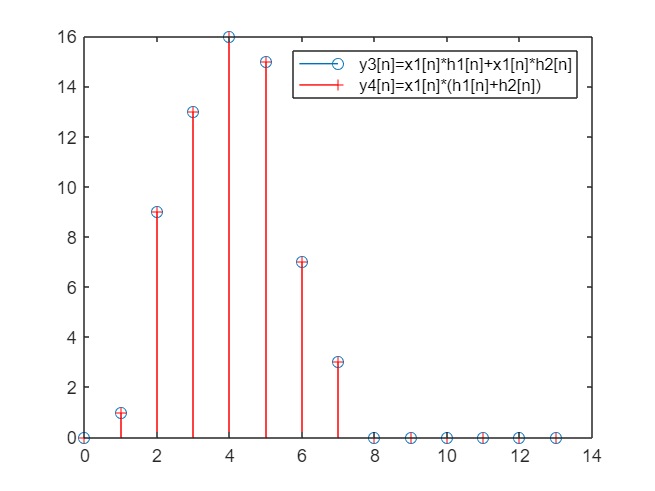

结论：卷积满足分配律。

(d)验证卷积的结合律，y5为分步计算x1与h1、h2的卷积；h0为h1和h2的卷积，y6为x1与h0的卷积，比较y5和y6是否一致。

%计算y5
w1 = conv(x1,h1)
y5 = conv(w1,h2)
%计算y6
h0 = conv(h1,h2)
y6 = conv(x1,h0)
%作图对比
figure
stem(0:17,y5)
hold on
stem(0:17,y6,'r','+')
legend('y5[n]=(x[n]*h1[n])*h2[n]','y6[n]=x[n]*(h1[n]*h2[n])')

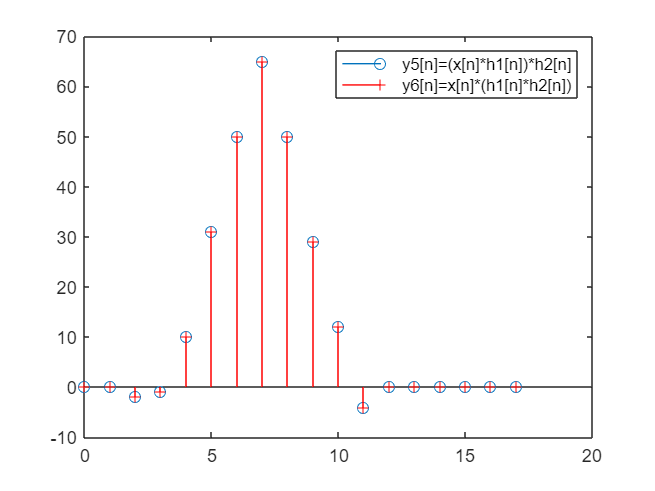

结论：y5等于y6，卷积的分配律成立。

(e)y7[n]等于x1[n]卷积h1[n]，y8[n]等于x1[n]卷积h1[n-2]，证明y8[n]=y7[n-2]

%计算y7，y8
x1 = [1 1 1 1 0 0 0 0 0 0]
h1 = [0 -1 3 0 4]
h2 = [0 2 5 4 -1]
y7 = conv(x1,h1)
h3 = [0 0 0 -1 3 0 4]
y8 = conv(x1,h3)
%平移y8
y80 = circshift(y8,-2)
%作图比较
figure
stem(0:13,y7)
hold on
stem(0:15,y80,'r','+')
legend('ye1[n]','ye2[n-2]')

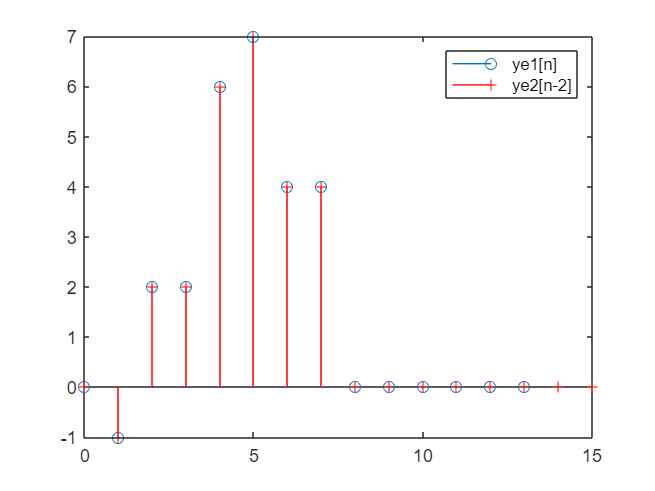

结论：ye1[n]=ye2[n-2]，证明完毕。

(f)题意：判断当存在非LTI系统时，串联的A、B系统处理信号是否与单一系统（A卷积B）处理信号结果一致

clc,clear
x1 = [1 1 1 1 0 0 0 0 0 0]
h1 = [0 -1 3 0 4]
h2 = [0 2 5 4 -1]
nx1 = 0:9
nh1 = 0:4
%计算w[n]
w2 = (nx1+2).*x1
%计算yf1[n]
yf1 = conv(w2,h1)

%定义hf1[n]
hf1 = [1 0 0 0 0]
%计算hserises[n]
hs = conv(hf1,h1)
%计算yf2[n]
yf2 = conv(hs,x1)
figure
stem(0:9+4,yf1)
hold on
stem(0:9+8,yf2,'r','+')
legend('yf1[n]','yf2[n]')

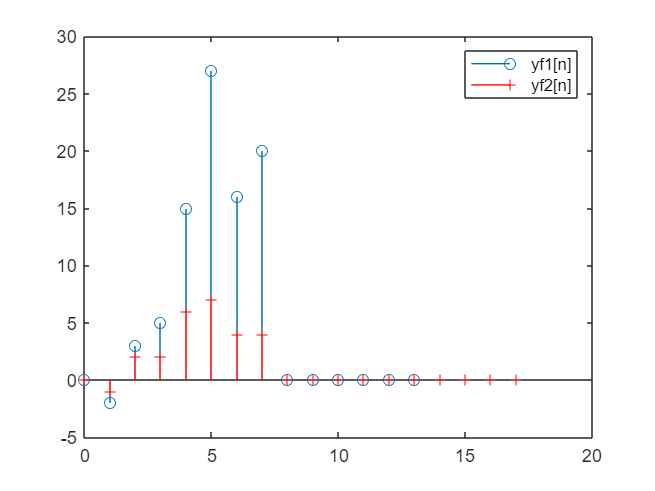

结论：如图所示，两个输出信号不相等。这不违反卷积的结合律，因为系统1不是LTI系统。

(g)题意：判断在一个系统为无记忆系统时，两个系统的斌概念是否满足卷积的分配率性质。

%定义yga[n]
xg = [2 0 0 0 0]
yga = xg.*xg
%定义ygb[n]
ygb = conv(h2,xg)
%yg1[n]
yga = [yga,[0 0 0 0]]
yg1 = yga+ygb
%hg1[n]
hg1 = [1 0 0 0 0]
%hparallel[n]
hparallel = hg1+h2
yg2 = conv(hparallel,xg)
%作图比较
figure
stem(0:8,yg1)
hold on
stem(0:8,yg2,'r','+')
legend('yg1[n]','yg2[n]')

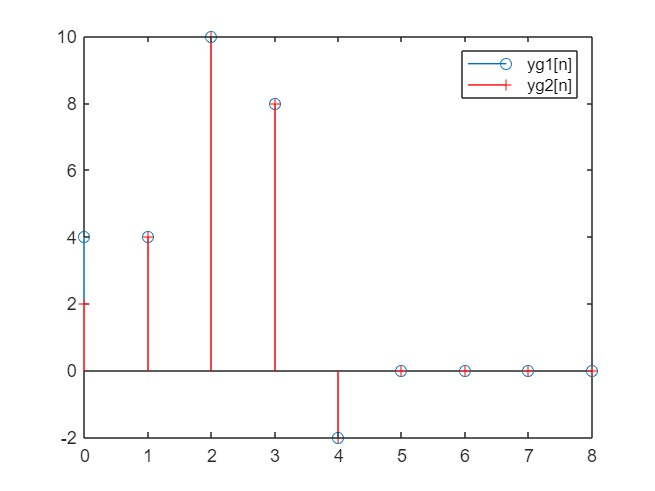

结论：如图所示，两个输出信号不相同。这不违反卷积的分配律性质，因为系统1是非LTI系统。